clc;
clear;
close all;

%% PARAMETERS
N = 1e4;              % Number of bits
Rb = 1e9;             % Bit rate (1 Gbps)
Fs = 10e9;            % Sampling frequency
samples_per_bit = Fs/Rb;

t = (0:N*samples_per_bit-1)/Fs;

%% ================= TRANSMITTER =================

% Generate random binary data
data = randi([0 1], 1, N);

% NRZ OOK modulation
nrz_signal = repelem(data, samples_per_bit);

% Optical power scaling
P_tx = 1;  % Transmit optical power
tx_signal = P_tx * nrz_signal;

%% ================= CHANNEL =================

% Add noise (AWGN)
SNR_dB = 20;
rx_signal = awgn(tx_signal, SNR_dB, 'measured');

%% ================= RECEIVER =================

% Photodetector (Optical → Electrical)
R = 1;  
elec_signal = R * rx_signal;

% Low-pass filter
Wn = (Rb)/(Fs/2);          % Normalized cutoff
b = fir1(100, Wn);         % FIR filter
filtered_signal = filter(b, 1, elec_signal);

% Sampling at bit intervals
samples = filtered_signal(samples_per_bit:samples_per_bit:end);

% Threshold detection
threshold = mean(samples);
rx_bits = samples > threshold;

%% ================= BER =================

[num_errors, BER] = biterr(data, rx_bits);
fprintf('Bit Error Rate (BER) = %e\n', BER);

Bit Error Rate (BER) = 5.036000e-01


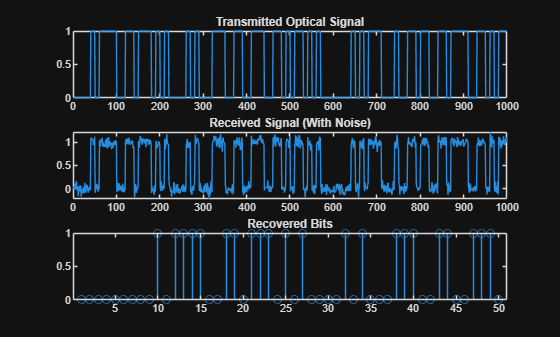


%% ================= PLOTS =================

figure;

subplot(3,1,1);
plot(tx_signal(1:1000));
title('Transmitted Optical Signal');

subplot(3,1,2);
plot(rx_signal(1:1000));
title('Received Signal (With Noise)');

subplot(3,1,3);
stem(rx_bits(1:50));
title('Recovered Bits');